clear
cd('C:\Users\Administrator\Desktop\Scene-Depth-Ordering\hazy_images\')
[fName,pName]=uigetfile({'*.png'},'Open');
if fName
   I=imread([pName fName]); 
end

[m,n,~]=size(I);
II=double(I)./255;

patch_size=35;  

atmosphere=get_atmospheric_light(II);
ATmosphere=reshape(repmat(atmosphere,[m*n,1]),[m,n,3]);
D=(sum((II-ATmosphere).^2,3)).^0.5;


D_patch=maxfilt2(D,patch_size);
D_patch=max(D_patch,eps);
D_max=max(D_patch(:));
D_min=min(D_patch(:));
depth_order=(D_patch-D_min)/(D_max-D_min);

weight=depth_order;

t_threshold_0=max((II-ATmosphere)./(0-ATmosphere),[],3);
t_threshold_1=max((II-ATmosphere)./(1-ATmosphere+1e-5),[],3);
t_threshold=max(t_threshold_0,t_threshold_1);
D_clear_max_threshold=(D_patch./(max(t_threshold,eps))-D_patch.*(1-weight))./max(weight,eps);
D_clear_max=prctile(D_clear_max_threshold,2,'all')

D_clear_max = 1.4491

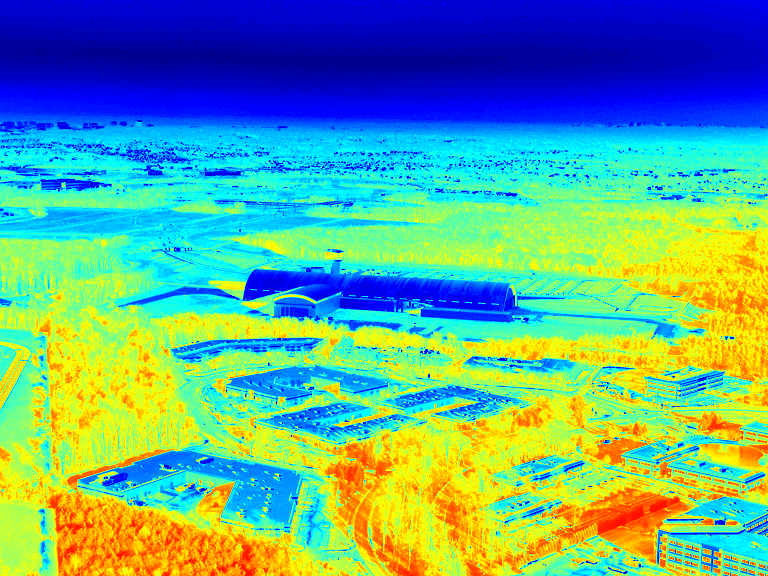

D_clear_max=max(D_clear_max,D_max);

D_clear=D_patch.*(1-weight)+D_clear_max.*weight;

D_sort=sort(reshape(D_clear,1,[]));
D_max=D_sort(floor(0.999*m*n));
imshow(D/D_max,'Border','tight')
colormap('jet')

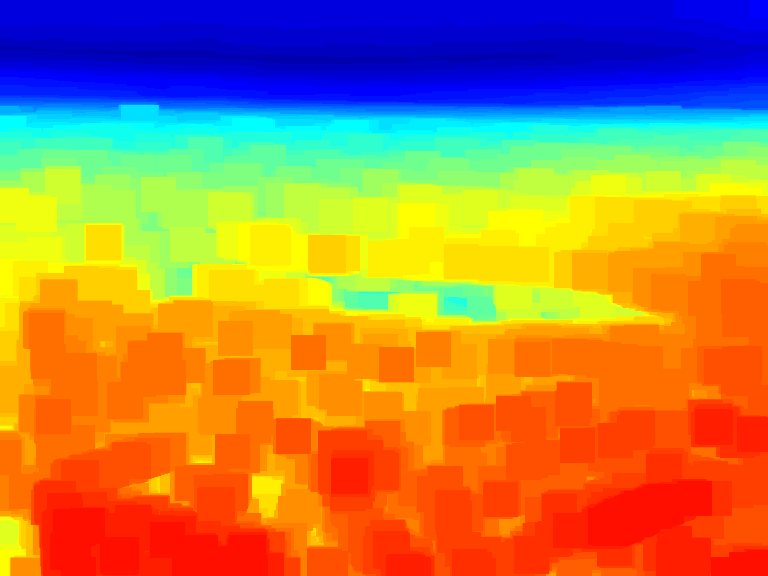

imshow(D_patch/D_max,'Border','tight')
colormap('jet')

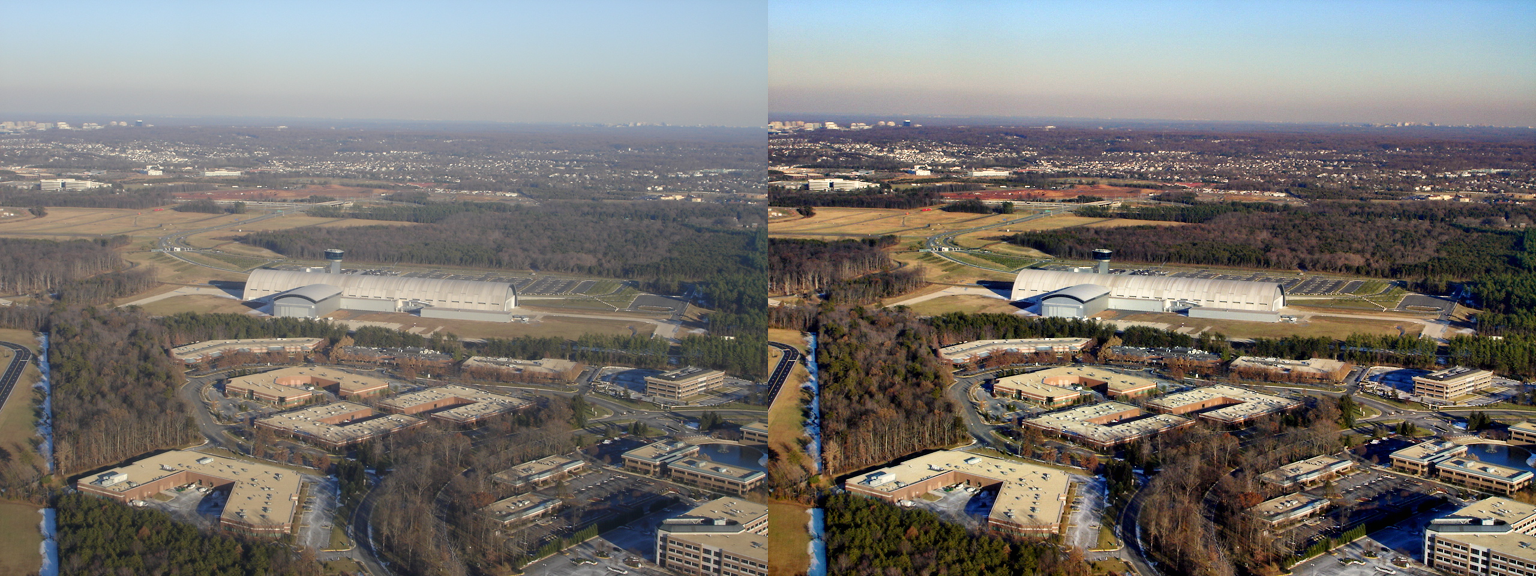


transmission=D_patch./D_clear;
transmission_final=guidedfilter(rgb2gray(II),transmission,patch_size,0.02);

image_dehaze=(II-ATmosphere)./repmat(transmission_final,1,1,3)+ATmosphere;
dehaze_final=ones(size(image_dehaze));
image_dehaze=min(max(image_dehaze,0),1);

for k=1:3
dehaze_final(:,:,k)=adapthisteq(image_dehaze(:,:,k),'ClipLimit',0.002);
end

imshow([II,dehaze_final],'Border','tight')